# Active Filter Modeling

Professor Ruben Flores

    - Angel Zayas Ortiz (B00607606)

    - Jose Cardona Ramos (Y00100717)

    - Luis Tejada Figueroa (Y00621391)

    - Miguel Ocasio Toledo (Y00609359)

## Part 1- Filter's transfer function H(s)

clc; clear; close all;

syms s Vin V1 Vout R1 R2 R3 C1 C2 A

% Write the Equation System using Node Current Method
eq1 = (Vin-V1)/R1 + (V1-0)/R2 - (V1-Vout)/(1/(C1*s)) - (V1-(Vout/A))/(1/(C2*s)) == 0;
eq2 = (V1-Vout)/(1/(C1*s)) + ((Vout/A)-Vout)/R3 == 0;

% Solve for V1 and Vout in terms of another variables
sol = solve([eq1, eq2], [V1, Vout]);

% Extract Vout and Calculate H(s)
H = sol.Vout/Vin;

% Display H(s) symbollically
disp('H(s) symbollically = ');

H(s) symbollically = 


pretty(H);

                                                                     A C1 R2 R3 s
-----------------------------------------------------------------------------------------------------------------------------------------------------
                                                                                                                              2                     2
R1 - R2 - A R1 + A R2 - C1 R1 R2 s - C2 R1 R2 s + A C1 R1 R2 s - A C1 R1 R3 s + A C2 R1 R2 s + A C1 R2 R3 s - C1 C2 R1 R2 R3 s  + A C1 C2 R1 R2 R3 s




% Evaluate Values
R1 = (9.76*(10^3));
R2 = (2.43*(10^3));
R3 = (196*(10^3));
C1 = (8.2*(10^-9));
C2 = (8.2*(10^-9));
A = 100000;

% Solve system with numeric values substituted
sol_num = solve(subs(eq1), subs(eq2), [V1, Vout]);

% Formulate H with numeric values
H_num = subs(sol_num.Vout/Vin);

% Get numerator and denominator of H
[num, den] = numden(H_num);

% Expand and convert to polynomial coefficients
num = expand(num);

num = sym2poly(num); 
den = sym2poly(den);

% Create transfer function model
sys = tf(num,den);

% Get numerator and denominator data
[numCoeff, denCoeff] = tfdata(sys, 'v');

% Convert coefficient vectors to string representations of polynomials
numStr = poly2str(numCoeff, 's');
denStr = poly2str(denCoeff, 's');

% Display the transfer function
disp('H(s) =');

H(s) =


disp(numStr);

   -4.645091795726962e+48 s


disp(denStr);

   -3.717522690357542e+44 s^2 + 1.354912920596599e+49 s + 8.718017475232342e+51


## Part 2- Filter's Transfer Function Pole and Zero Locations

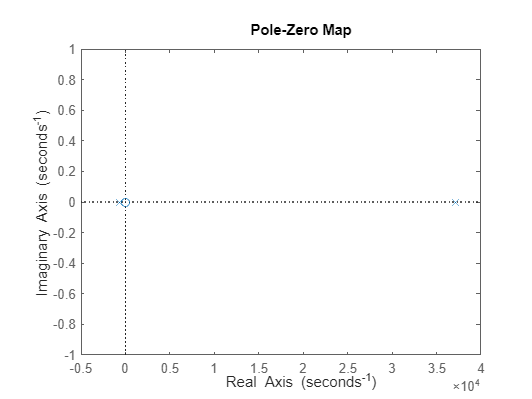

% Calculate and Plot the pzmap
pzmap(sys);

title('Pole-Zero Map');

## Part 3- Filter's Frequency Response (Bode Diagram)

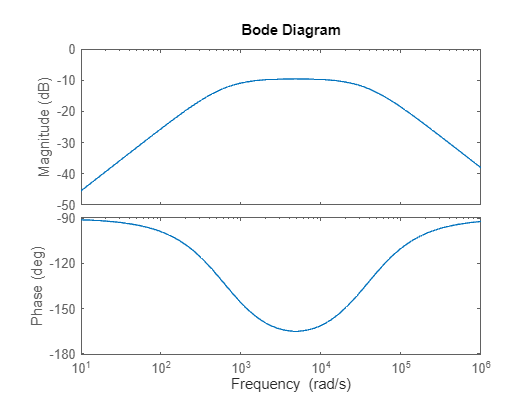

% Calculate and Plot the Bode Diagram
bode(sys);
title('Bode Diagram');

## Part 4- Filter's Parameters

% Frequency vector for Bode analysis
f = logspace(1, 8, 1000); % from 10^1 to 10^8 with 1000 points logarithmically spaced
w = 2*pi*f; % convert frequency to radians per second

% Get magnitude and phase
[mag, phase, w] = bode(sys, w);

% Convert magnitude from dB to absolute value
mag = 10.^(mag/20);

% Find the maximum magnitude and its index
[max_mag, idx_max] = max(mag);

% Central frequency (where magnitude is maximum)
f0 = w(idx_max)/(2*pi);

% Find -3 dB points around the peak
mag_3dB = max_mag/sqrt(2);

% Find indices where the response crosses mag_3dB
idxs = find(mag >= mag_3dB);
idx_low = idxs(1);
idx_high = idxs(end);

% -3 dB frequencies
f_low = w(idx_low)/(2*pi);
f_high = w(idx_high)/(2*pi);

% Bandwidth calculation
BW = f_high - f_low;

% Quality factor calculation
Q = f0 / BW;

% Display Results
disp(['Central Frequency (f0) = ', num2str(f0), ' Hz']);

Central Frequency (f0) = 767.1581 Hz


disp(['Bandwidth (BW) = ', num2str(BW), ' Hz']);

Bandwidth (BW) = 99999990 Hz


disp(['Quality Factor (Q) = ', num2str(Q)]);

Quality Factor (Q) = 7.6716e-06


## Part 5- Impulse Response

% Calculate the impulse response
syms t s
f = dirac(t); % Time domain of impulse
F = laplace(f, t, s); % Laplace domain of impulse

% Find the Vout(s) expression
Vout_s = F*H_num % Vout(s)= Vin(s)*H(s)

$$Vout\_s = -\frac{4645091795726962332131279469732634086604800000000\,s}{-371752269035754246939545363596206989306206875\,s^{2}+13549129205965986018294677720127969728797616373760\,s+8718017475232342151081628819752698918076696582160384}$$


% Calculate the inverse laplace transform
Vout_t = ilaplace(Vout_s, s, t); % Response represented by the time domain expression
disp('Vout(t) = ');

Vout(t) = 


disp(Vout_t);

$$\frac{377789318629571617095680000\,{\mathrm{e}}^{\frac{820066609474468037607553847263232\,t}{45000917505215587181401608375}}\,\left(\cosh\left(\frac{37778931862957161709568\,\sqrt{504467275606884090901}\,t}{45000917505215587181401608375}\right)+\frac{43413964823\,\sqrt{504467275606884090901}\,\sinh\left(\frac{37778931862957161709568\,\sqrt{504467275606884090901}\,t}{45000917505215587181401608375}\right)}{1008934551213768181802}\right)}{30234932396214386281281}$$

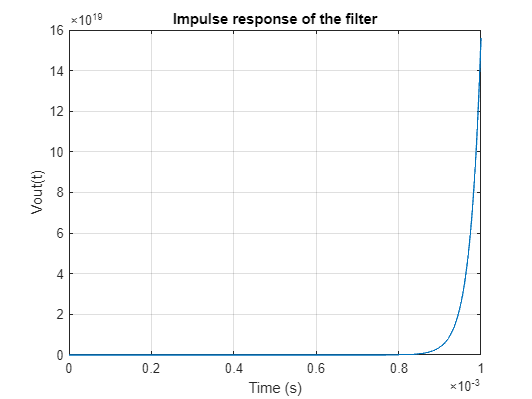


% Define the time range
t_vals = linspace(0, 1e-3, 1000);  % 1 ms range with 1000 points

% Numerically evaluate the impulse response
Vout_t_vals = double(subs(Vout_t, t, t_vals));

% Plot the numerical impulse response
figure;
plot(t_vals, Vout_t_vals);
xlabel('Time (s)');
ylabel('Vout(t)');
title('Impulse response of the filter');
grid on;

## Part 6- Step Response

% Calculate the step response
syms t s
f = heaviside(t); % Time domain of step function
F = laplace(f, t, s); % Laplace domain of step function

% Find the Vout(s) expression
Vout_s = F*H_num % Vout(s)= Vin(s)*H(s)

$$Vout\_s = -\frac{4645091795726962332131279469732634086604800000000}{-371752269035754246939545363596206989306206875\,s^{2}+13549129205965986018294677720127969728797616373760\,s+8718017475232342151081628819752698918076696582160384}$$


% Calculate the inverse laplace transform
Vout_t = ilaplace(Vout_s, s, t); % Response represented by the time domain expression
disp('Vout(t) = ');

Vout(t) = 


disp(Vout_t);

$$\frac{14883750000\,\sqrt{504467275606884090901}\,\sinh\left(\frac{37778931862957161709568\,\sqrt{504467275606884090901}\,t}{45000917505215587181401608375}\right)\,{\mathrm{e}}^{\frac{820066609474468037607553847263232\,t}{45000917505215587181401608375}}}{504467275606884090901}$$

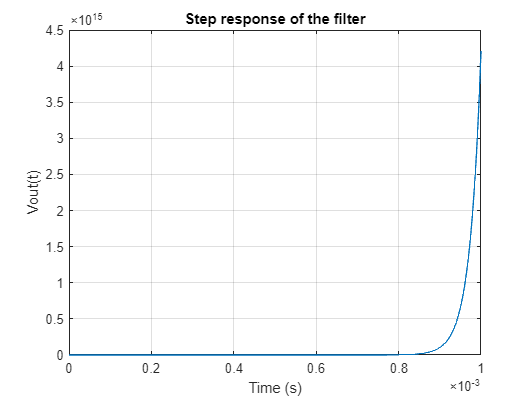


% Define the time range
t_vals = linspace(0, 1e-3, 1000);  % 1 ms range with 1000 points

% Numerically evaluate the impulse response
Vout_t_vals = double(subs(Vout_t, t, t_vals));

% Plot the numerical impulse response
figure;
plot(t_vals, Vout_t_vals);
xlabel('Time (s)');
ylabel('Vout(t)');
title('Step response of the filter');
grid on;

## Part 7- Responses to different input signals

% Time vector
t = 0:1e-6:0.01; % 10 ms with 1 us sampling interval

% Define input signals
x1 = 200 * cos(2 * pi * 1000 * t); % 1 kHz
x2 = 200 * cos(2 * pi * 100 * t); % 100 Hz
x3 = 200 * cos(2 * pi * 10000 * t); % 10 kHz
T = 1e-3; % period 1 ms
D = 0.25; % duty cycle 25%
A = 200e-3;
x4 = A * double(mod(t, T) < D * T); % Rectangular pulse train

% Response to 1 kHz signal
A=200*(10^-3);
omega = 2 * pi * 1000;

[zeta] = damp(sys);

H_jw = subs(H_num, s, 1j*omega);

magH_jw = abs(H_jw);
phaseH_jw = angle(H_jw);

Vout_t = A * magH_jw * exp(-zeta * t) .* cos(omega * t + phaseH_jw);

disp('Time Domain Response to 200cos(2π × 1000 t) mV');

Time Domain Response to 200cos(2π × 1000 t) mV


disp(Vout_t);
figure;
plot(t, Vout_t);
xlabel('Time (s)');
ylabel('Vout(t)');
title('Time Domain Response to 200cos(2π × 1000 t) mV');
grid on;

% Response to 100 Hz signal
A=200*(10^-3);
omega = 2 * pi * 100;

[zeta] = damp(sys);

H_jw = subs(H_num, s, 1j*omega);

magH_jw = abs(H_jw);
phaseH_jw = angle(H_jw);

Vout_t = A * magH_jw * exp(-zeta * t) .* cos(omega * t + phaseH_jw);

disp('Time Domain Response to 200cos(2π × 100 t) mV');
disp(Vout_t);

figure;
plot(t, Vout_t);
xlabel('Time (s)');
ylabel('Vout(t)');
title('Time Domain Response to 200cos(2π × 100 t) mV');
grid on;

% Response to 10 kHz signal
A=200*(10^-3);
omega = 2 * pi * 10000;

[zeta] = damp(sys);

H_jw = subs(H_num, s, 1j*omega);

magH_jw = abs(H_jw);
phaseH_jw = angle(H_jw);

Vout_t = A * magH_jw * exp(-zeta * t) .* cos(omega * t + phaseH_jw);

disp('Time Domain Response to 200cos(2π × 10000 t) mV');
disp(Vout_t);

figure;
plot(t, Vout_t);
xlabel('Time (s)');
ylabel('Vout(t)');
title('Time Domain Response to 200cos(2π × 10000 t) mV');
grid on;

% Response to Rectangular Pulse Train
integralPart = int(exp(-s * t) * x4_t, t, 0, D * T);
X4_s = simplify(integralPart / (1 - exp(-s * T))); % Laplace Transform of the rectangular waveform

Vout_s = X4_s*H_num; % Vout(s)= Vin(s)*H(s)

Vout_t = ilaplace(Vout_s, s, t); % Response represented by the time domain expression
disp('Vout(t) = ')
disp(Vout_t);

figure;
plot(t, Vout_t);
xlabel('Time (s)');
ylabel('Vout(t)');
title('Time Domain Response to Rectangular Waveform');
grid on;